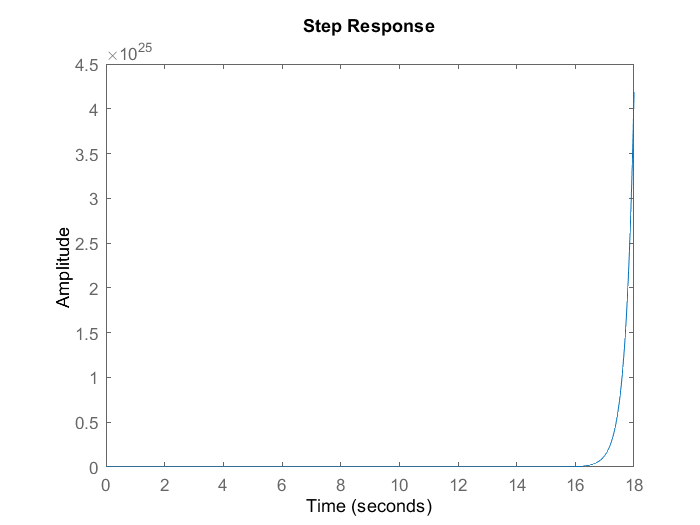

mc = 1.5;
mp = 0.5;
g = 9.82;
L = 1;
d1 = 0.1;
d2 = 0.1;
A = [0           0               1                 0;
     0           0               0                 1;
     0       (g*mp)/mc        -d1/mc          -d2/(L*mc);
     0    (g*(mc+mp))/(mc*L)   -d1/(L*mc)    -(d2*(mc+mp))/(L*L*mc*mp)];
B = [0 0 1/mc 1/(L*mc)]';
C1 = [0 1 0 0]; %q2 as output
C2 = [1 0 0 0]; %q1 as output 
D = 0;
sys1 = ss(A,B,C1,D);
sys2 = ss(A,B,C2,D);
step(sys1)

%Part 1
Q = ctrb(sys1); % Returns matrix Q
i = rank(Q) %If rank(i) is 4 then the system is controllable.

i = 4

R = obsv(sys1);
j = rank(R) %If rank(j) is 4 then system is observable.

j = 3

k = rank(obsv(sys2))

k = 4

l = rank(ctrb(sys2))

l = 4

%Part 2
%When q1 is taken as the output then the system is not
%controllable and thus it cannot be made stable.

%Part 3
%eigen = eig(A)
%Since one of the eigen value is positive ,so we 
%have to correctly position the eigenvalues.
des_eig = [-1.5; -2.5; -4.0; -10.5];
K = place(A,B,des_eig)

K =   -24.0580  206.2146  -34.5576   61.8076


%Part 4
Q = [1 0 0 0;
     0 1 0 0;
     0 0 1 0;
     0 0 0 1];
R = 1;
K = lqr(A,B,Q,R)

K =    -1.0000   53.9908   -2.9295   15.0574


new_eig = eig(A-B*K)

new_eig =   -4.0119 + 0.0000i
  -3.2869 + 0.0000i
  -0.5599 + 0.4277i
  -0.5599 - 0.4277i


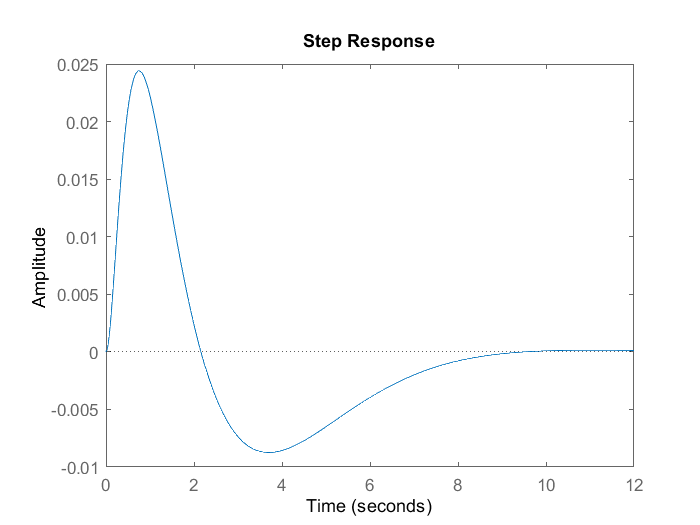

%Since the eigenvalues are negative,therefore it is correct.
A1 = A-B*K;
New = ss(A1,B,C1,D);
step(New)